%% ========================================================================
%  FOOOF ANALYSIS SCRIPT: NARROW-BAND VS BROAD-BAND THETA
%  ========================================================================
%  Goal: Separate the 1/f slope of oscillatory peaks to ensure a correct 
%  interpretation between children and adults groups.
%
%  Dependencies & Versions tested:
%  - MATLAB   : R2023a+ (with Python interface configured)
%  - EEGLAB   : 2025.1.0
%  - Python   : 3.11
%  - FOOOF    : v1.1.0 (specparam)
% =========================================================================

clear all; close all; clc;
restoredefaultpath;

%% 0. CONFIGURATION PARAMETERS

% Python Path (Mac/Linux: run "which python3" in terminal | Windows: "where python")
python_path = '/opt/homebrew/bin/python3.11'; 

% Paths
eeglab_path  = '/Users/meissane/Downloads/eeglab2025.1.0/';
dossier      = '/Users/meissane/Documents/ECM/SSE/Code/SEED_EEG_data_ds/';
dossier_save = '/Users/meissane/Desktop/SEED_EEG_data_ds/preprocessed/';

% Subject & Group Info
subject      = 'DS2605';
group        = 'adult';   % 'adult' or 'child'

%% 1. INITIALISATION & IMPORT

% Python BEFORE eeglab, and AFTER clear all
pyenv('Version', python_path, 'ExecutionMode', 'OutOfProcess');
try
    py.importlib.import_module('fooof');
    fprintf('FOOOF import OK\n');
    
    python_ver = char(py.sys.version);
    
    try
        py.importlib.import_module('importlib.metadata');
        try
            fooof_ver = char(py.importlib.metadata.version('fooof'));
        catch
            fooof_ver = char(py.importlib.metadata.version('specparam'));
        end
    catch
        fooof_ver = 'unknown_version'; 
    end
    fprintf('  FOOOF/Specparam version : %s\n', fooof_ver);
    
catch e
    error('Python/FOOOF failed: %s', e.message);
end

FOOOF import OK


  FOOOF/Specparam version : 1.1.1



% Initialize EEGLAB
addpath(eeglab_path);
[ALLEEG, EEG, CURRENTSET] = eeglab;

Disable MATLAB Copilot in settings to hide "Explain Error" buttons
Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Fileio" v260210 to the path
EEGLAB: adding "ICLabel" v1.7 (see >> help eegplugin_iclabel)
EEGLAB: adding "SIFT" v1.6 (see >> help eegplugin_sift)
EEGLAB: adding "bva-io" v1.74 (see >> help eegplugin_bva_io) - new version 1.75 available
EEGLAB: adding "clean_rawdata" v2.11 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.6 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
Disable MATLAB Copilot in settings to hide "Explain Error" buttons


Disable MATLAB Copilot in settings to hide "Explain Error" buttons
Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Fileio" v260210 to the path
EEGLAB: adding "ICLabel" v1.7 (see >> help eegplugin_iclabel)
EEGLAB: adding "SIFT" v1.6 (see >> help eegplugin_sift)
EEGLAB: adding "bva-io" v1.74 (see >> help eegplugin_bva_io) - new version 1.75 available
EEGLAB: adding "clean_rawdata" v2.11 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.6 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
Disable MATLAB Copilot in settings to hide "Explain Error" buttons


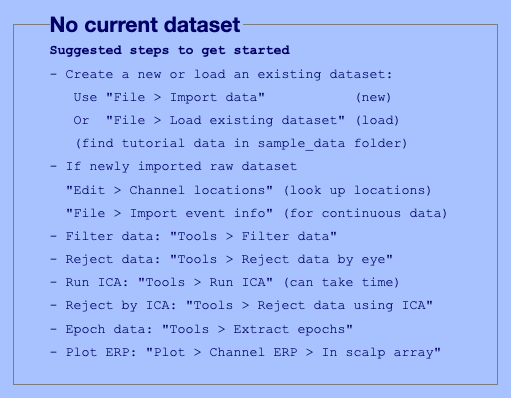

% Initialize EEGLAB
addpath(eeglab_path);
[ALLEEG, EEG, CURRENTSET] = eeglab;


% Load Dataset
EEG = pop_loadset('filename', [subject 'encoding_preprocessed_continuous.set'], ...
                  'filepath', dossier);

pop_loadset(): loading file /Users/meissane/Documents/ECM/SSE/Code/SEED_EEG_data_ds/DS2605encoding_preprocessed_continuous.set ...
Reading float file '/Users/meissane/Documents/ECM/SSE/Code/SEED_EEG_data_ds/DS2605encoding_preprocessed_continuous.fdt'...


EEG = eeg_checkset(EEG);
fs = EEG.srate;

fprintf('Loaded : %s\n', EEG.filename);

Loaded : DS2605encoding_preprocessed_continuous.set


fprintf('  Channels      : %d\n',   EEG.nbchan);

  Channels      : 63


fprintf('  Samples       : %d\n',   EEG.pnts);

  Samples       : 103657


fprintf('  Sampling rate : %d Hz\n', EEG.srate);

  Sampling rate : 500 Hz


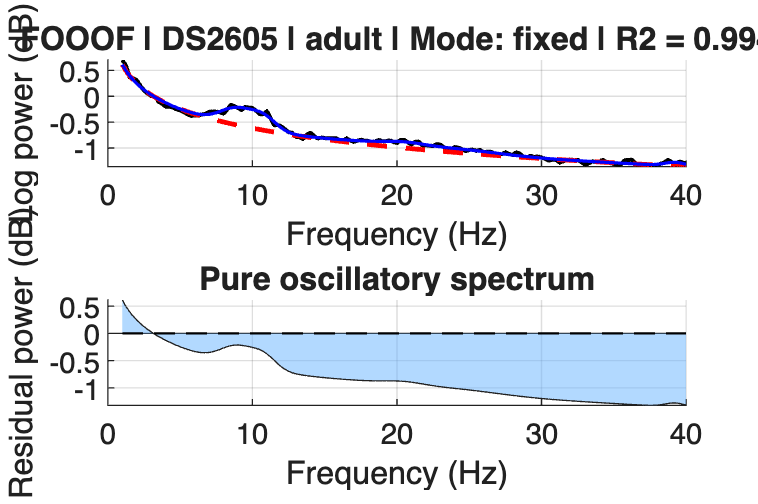


% Safety check
if EEG.trials > 1
    error('Loaded file contains epochs. FOOOF requires continuous data.');
end

%% 2. DEFINE FRONTAL THETA CLUSTER

theta_chans = {'Fz', 'F1', 'F2', 'FCz', 'FC1', 'FC2'};
chan_idx_fooof = [];
for c = 1:length(theta_chans)
    idx = find(strcmpi({EEG.chanlocs.labels}, theta_chans{c}));
    if ~isempty(idx)
        chan_idx_fooof(end+1) = idx;
    end
end

if isempty(chan_idx_fooof)
    error('No frontal channels found. Check channel labels.');
end

%% PRE-WELCH: remove residual high-amplitude windows
win_sec    = 2;                        
win_samps  = win_sec * fs;
n_wins     = floor(EEG.pnts / win_samps);
data_clust = EEG.data(chan_idx_fooof, :);
amp_thresh = 5;                        

keep_mask = true(1, n_wins);
for w = 1:n_wins
    seg = data_clust(:, (w-1)*win_samps+1 : w*win_samps);
    if any(abs(seg(:)) > amp_thresh * std(data_clust(:)))
        keep_mask(w) = false;
    end
end

clean_data = [];
for w = 1:n_wins
    if keep_mask(w)
        clean_data = [clean_data, ...
            data_clust(:, (w-1)*win_samps+1 : w*win_samps)];
    end
end

%% 3. COMPUTE POWER SPECTRUM (Welch)

nfft    = 4 * fs;
overlap = round(nfft * 0.5);       
win     = hanning(nfft);

clean_pnts = size(clean_data, 2);
n_nonoverlap_wins = floor((clean_pnts - overlap) / (nfft - overlap));

if n_nonoverlap_wins < 8
    warning('PSD estimate unstable. Consider reducing nfft.');
end

freq_range = [1 40];

psd_cluster = zeros(size(clean_data, 1), nfft/2 + 1);
for ci = 1:size(clean_data, 1)
    data_ch = clean_data(ci, :);   
    [pxx, freqs_all] = pwelch(data_ch, win, overlap, nfft, fs);
    psd_cluster(ci, :) = pxx';
end

psd_mean = mean(psd_cluster, 1);

freq_idx  = freqs_all >= freq_range(1) & freqs_all <= freq_range(2);
freqs     = freqs_all(freq_idx)';
psd_final = psd_mean(freq_idx);

psd_final = abs(psd_final);
psd_final(psd_final == 0) = eps;

%% 4. FIT FOOOF MODEL

r2_results = struct();

for mode = {'fixed', 'knee'}
    fm_test = py.fooof.FOOOF(pyargs(...
        'peak_width_limits', py.tuple({1.0, 8.0}), ...
        'max_n_peaks',       int32(6), ...
        'min_peak_height',   0.1, ...
        'peak_threshold',    1.0, ...
        'aperiodic_mode',    mode{1}, ...  
        'verbose',           false));
    
    fm_test.fit(py.numpy.array(freqs), py.numpy.array(psd_final), ...
               py.list({double(freq_range(1)), double(freq_range(2))}));
    
    r2_results.(mode{1}) = double(fm_test.r_squared_);
end

r2_delta = r2_results.knee - r2_results.fixed;
KNEE_THRESHOLD = 0.02;   
if r2_delta > KNEE_THRESHOLD
    best_mode = 'knee';
else
    best_mode = 'fixed';
end

fm = py.fooof.FOOOF(pyargs(...
    'peak_width_limits', py.tuple({1.0, 8.0}), ...
    'max_n_peaks',       int32(6), ...
    'min_peak_height',   0.1, ...
    'peak_threshold',    1.0, ...
    'aperiodic_mode',    best_mode, ...
    'verbose',           false));

fm.fit(py.numpy.array(freqs), py.numpy.array(psd_final), ...
       py.list({double(freq_range(1)), double(freq_range(2))}));

r_squared = double(fm.r_squared_);

if r_squared < 0.90
    error('R2 fit unacceptable. Exclude this subject.');
elseif r_squared < 0.95
    warning('Marginal fit. Verify plot.');
end

%% 5. EXTRACT APERIODIC PARAMETERS

aperiodic = double(py.array.array('d', fm.aperiodic_params_));

if strcmp(best_mode, 'knee')
    aperiodic_exp    = aperiodic(3);
    aperiodic_offset = aperiodic(1);
    aperiodic_knee   = aperiodic(2);
else
    aperiodic_exp    = aperiodic(2);
    aperiodic_offset = aperiodic(1);
    aperiodic_knee   = NaN;
end

%% 6. EXTRACT OSCILLATORY PEAKS

band_names  = {'delta', 'theta', 'alpha', 'beta', 'gamma'};
band_ranges = [1 4; 4 8; 8 13; 13 30; 30 45];

try
    peaks_raw    = double(py.array.array('d', fm.peak_params_.flatten()));
    peaks_matrix = reshape(peaks_raw, 3, [])';
catch
    peaks_matrix = [];
end

%% 7. COMPUTE THETA POWER

freqs_model = double(py.array.array('d', fm.freqs));
psd_log     = double(py.array.array('d', fm.power_spectrum));   
ap_fit      = double(py.array.array('d', py.getattr(fm, '_ap_fit'))); 
psd_flat    = double(py.array.array('d', fm.fooofed_spectrum_)); 

theta_idx = freqs_model >= 4 & freqs_model <= 8;

psd_lin    = 10.^psd_log;
ap_fit_lin = 10.^ap_fit;

theta_total = trapz(freqs_model(theta_idx), psd_lin(theta_idx));
theta_narrowband = trapz(freqs_model(theta_idx), psd_lin(theta_idx) - ap_fit_lin(theta_idx));
theta_narrowband = max(0, theta_narrowband); 

theta_peaks = [];
if ~isempty(peaks_matrix)
    for p = 1:size(peaks_matrix, 1)
        if peaks_matrix(p,1) >= 4 && peaks_matrix(p,1) < 8
            theta_peaks(end+1, :) = peaks_matrix(p, :);
        end
    end
end

%% 8. VISUALISATION

fooofed_spectrum = double(py.array.array('d', fm.get_model('full', 'log')));

figure('Name', ['FOOOF ' subject ' (' group ')'], 'Color', 'w', 'Position', [50 50 900 600]);

ax1 = subplot(2,1,1); hold on;
plot(freqs_model, psd_log,          'k',   'LineWidth', 1.5);
plot(freqs_model, ap_fit,           'r--', 'LineWidth', 1.8);
plot(freqs_model, fooofed_spectrum, 'b',   'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('Log power (dB)');
title(sprintf('FOOOF | %s | %s | Mode: %s | R2 = %.3f', subject, group, best_mode, r_squared));
grid on; set(ax1, 'FontSize', 11, 'Box', 'off');

ax2 = subplot(2,1,2); hold on;
area(freqs_model, psd_flat, 'FaceColor', [0.4 0.7 1.0], 'FaceAlpha', 0.5);
plot(freqs_model([1 end]), [0 0], 'k--', 'LineWidth', 0.8);

if ~isempty(theta_peaks)
    for p = 1:size(theta_peaks, 1)
        xline(theta_peaks(p,1), 'r--', 'LineWidth', 1.2);
    end
end

xlabel('Frequency (Hz)'); ylabel('Residual power (dB)');
title('Pure oscillatory spectrum');
set(ax2, 'FontSize', 11, 'Box', 'off'); grid on;


%% 9. SAVE RESULTS

fooof_results.subject            = subject;
fooof_results.group              = group;
fooof_results.python_version     = python_ver;       
fooof_results.fooof_version      = fooof_ver;        
fooof_results.aperiodic_mode     = best_mode;        
fooof_results.aperiodic_offset   = aperiodic_offset;
fooof_results.aperiodic_exp      = aperiodic_exp;
fooof_results.aperiodic_knee     = aperiodic_knee;   
fooof_results.r_squared          = r_squared;
fooof_results.r_squared_fixed    = r2_results.fixed; 
fooof_results.r_squared_knee     = r2_results.knee;  
fooof_results.peaks              = peaks_matrix;
fooof_results.theta_peaks        = theta_peaks;      
fooof_results.theta_total_lin    = theta_total;      
fooof_results.theta_narrow_lin   = theta_narrowband; 
fooof_results.freqs              = freqs_model;
fooof_results.psd_log            = psd_log;
fooof_results.ap_fit             = ap_fit;
fooof_results.psd_flat           = psd_flat;
fooof_results.frontal_chans      = theta_chans;      
fooof_results.chan_idx           = chan_idx_fooof;   

save(fullfile(dossier_save, [subject '_fooof_results.mat']), 'fooof_results');

Error using save
Cannot create 'DS2605_fooof_results.mat' because '/Users/meissane/Desktop/SEED_EEG_data_ds/preprocessed' does not exist.

fprintf('Run complete.\n');